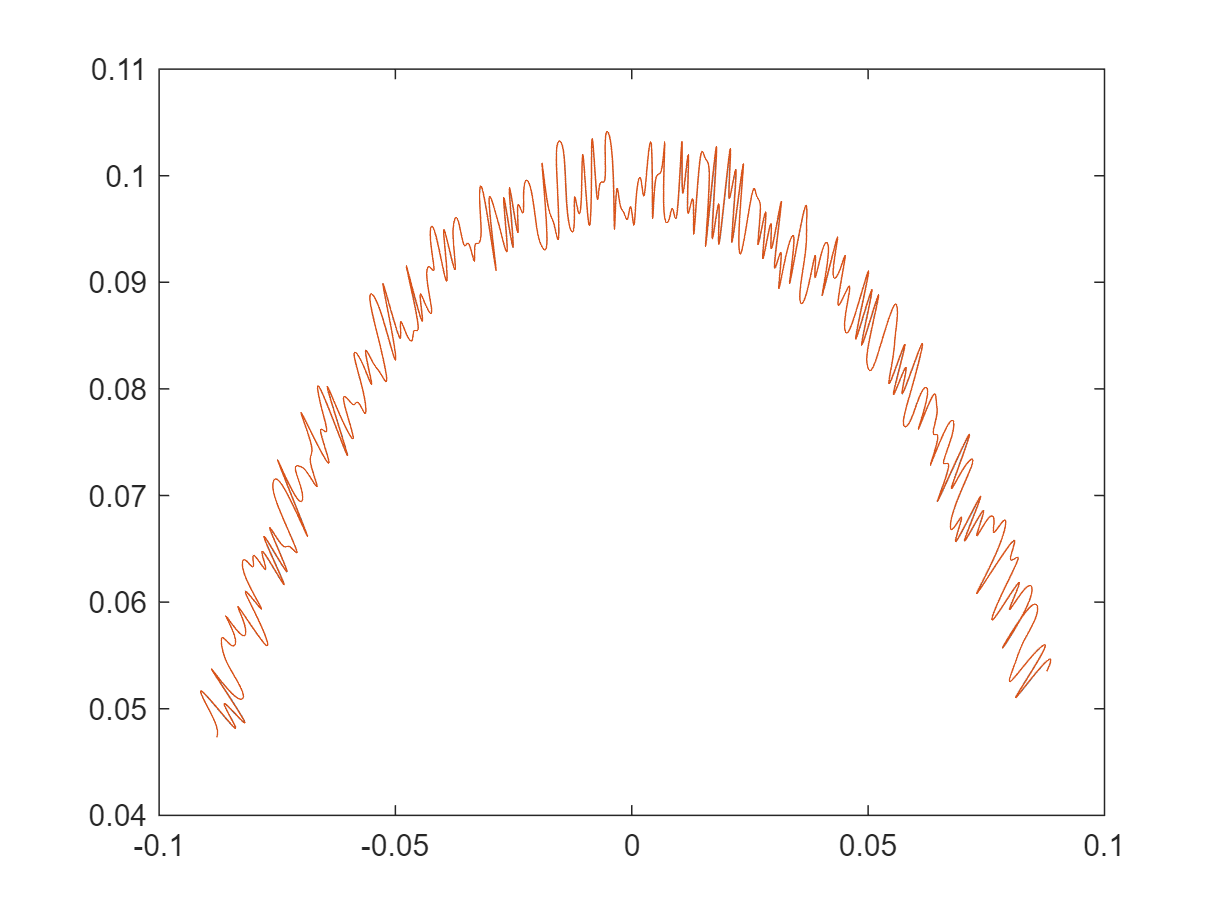

addpath(genpath('../funcs'));

load("../output_data/tool/toolTheo.mat");

k = 3;
u = 0:0.0001:1;
[toolPt1,toolBform1] = bsplinePts_spapi(toolFit,k,u, ...
    'ParamMethod','centripetal','CoordinateType','Cartesian');
[toolPt2,toolBform2] = bsplinePts_spapi(toolFit,k,u, ...
    'ParamMethod','centripetal','CoordinateType','Polar');

figure;
plot(toolPt1(1,:),toolPt1(2,:));
hold on;
plot(toolPt2(1,:).*cos(toolPt2(2,:)),toolPt2(1,:).*sin(toolPt2(2,:)));

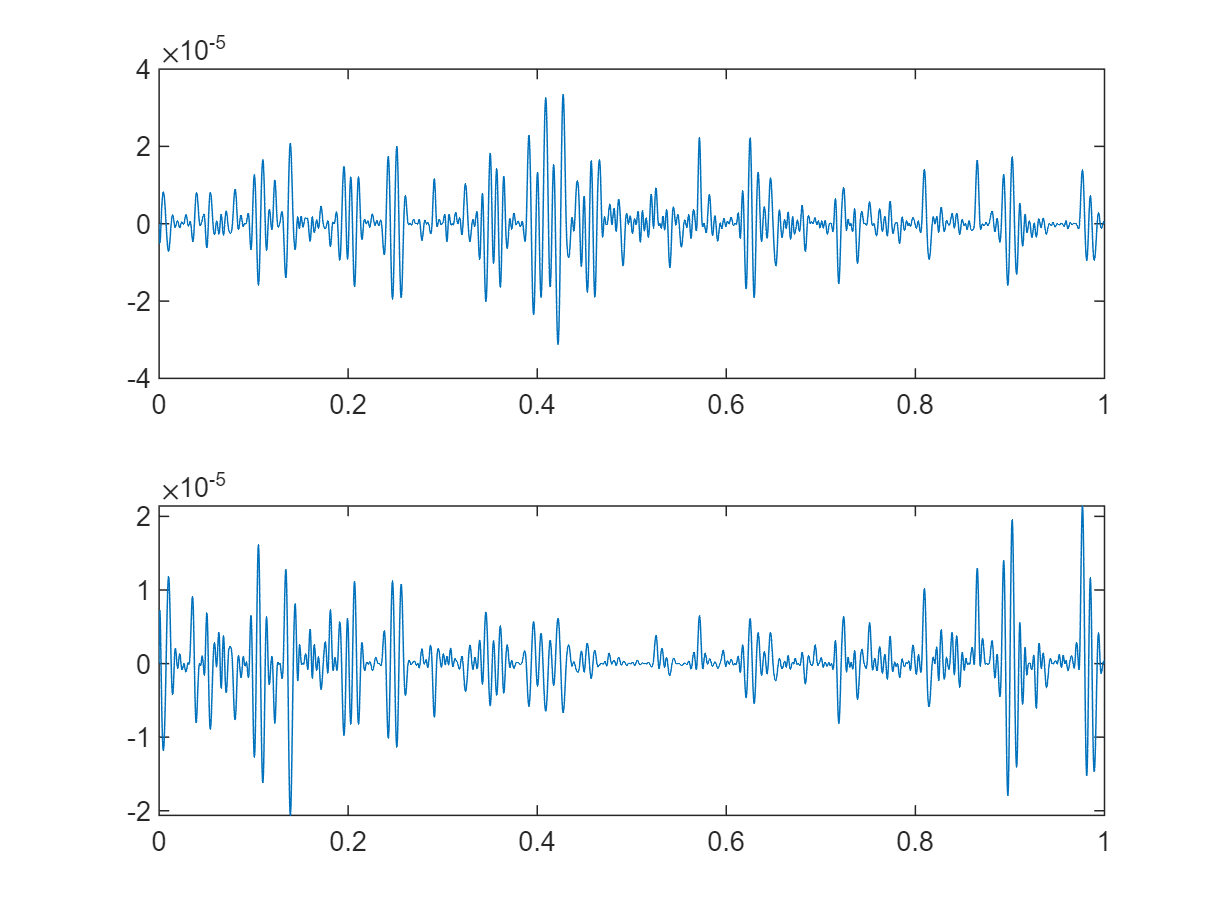


figure;
tiledlayout(2,1);
nexttile;
plot(u, toolPt1(1,:) - toolPt2(1,:).*cos(toolPt2(2,:)));
nexttile;
plot(u, toolPt1(2,:) - toolPt2(1,:).*sin(toolPt2(2,:)));

rmpath(genpath('../funcs'));

结果说明：B样条插值，或者说，构造B样条的时候，控制点的坐标是以哪种坐标系的形式给出并不会显著影响B样条插值的结果，定性分析，不会影响其连续性和微分性质。